## **SIO 207A HW-4**

**Ruipu Ji**

Given the impulse response: $h\left(n\right)=\delta \left(n\right)-\frac{1}{2}\delta \left(n-4\right)$.

#### A. Plot *h*(*n*) and the zero locations of *H*(*z*). Augment *h*(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*(*k*) vs ω to illustrate the amplitude and phase distortion caused by the multipath.

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultTextFontSize', 12);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

Plot the impulse response *h*(*n*) and zero locations of *H*(*z*).

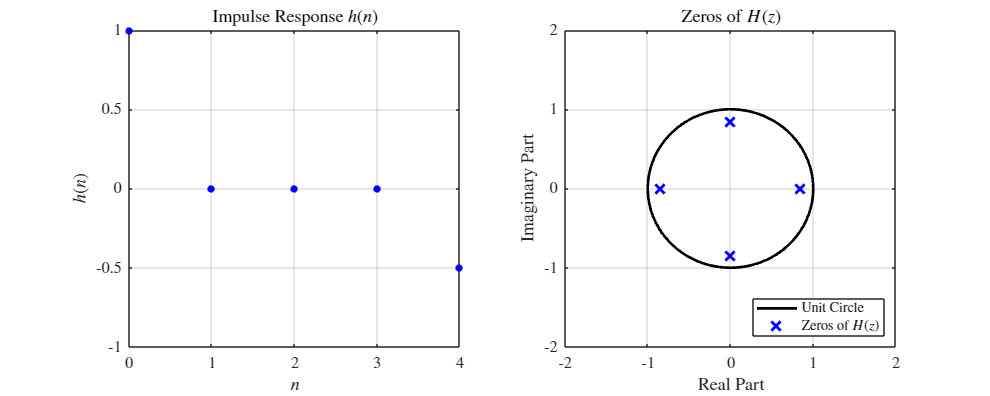

% Define the impulse response h(n).
n = (0:1:4)'; 
h = (n==0) - 0.5*(n==4);

% Calculate roots of the polynomial.
H_zeros = roots(h);

figure('Position',[0 0 1000 400]);

% Plot the impulse response h(n).
subplot(1,2,1);
hold on;
scatter(n, h, 30, 'o', 'b', 'filled');
grid on;
box on;
xlim([0 4]);
xticks(0:1:4);
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$n$');
ylabel('$h(n)$');
title('Impulse Response $h(n)$');

% Plot the zero locations of H(z).
subplot(1,2,2);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the zero locations.
plot(real(H_zeros), imag(H_zeros), 'x', 'Color', 'b', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H(z)$');
legend('Unit Circle', 'Zeros of $H(z)$', 'Location', 'southeast');

Figure A1. Impulse response function *h*(*n*) and zero locations of *H*(*z*).

Augment *h*(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*(*k*) vs ω.

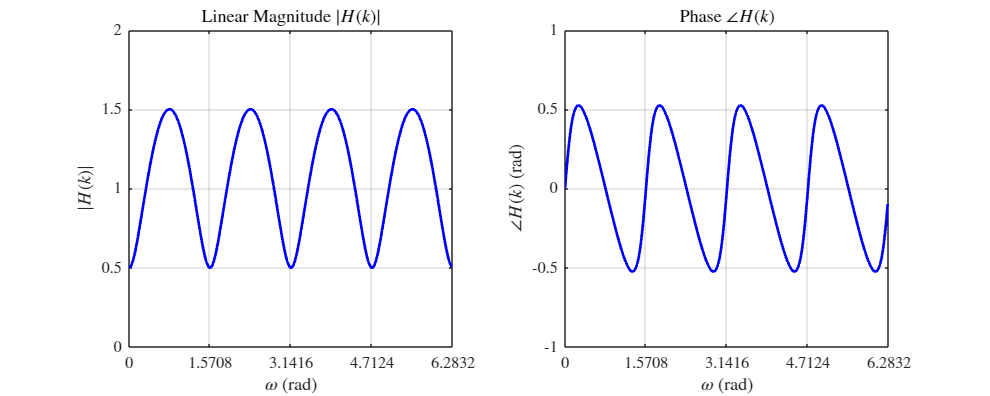

% Zero-pad h(n) with zeros out to NFFT=256.
NFFT = 256;
h_NFFT = padarray(h, NFFT-size(h,1), 'post'); 

% Perform FFT on the padded h(n), then calculate linear magnitude and phase.
H_NFFT = fft(h_NFFT); % FFT.
H_NFFT_magnitude = abs(H_NFFT); % Linear magnitude.
H_NFFT_phase = angle(H_NFFT); % Phase.

% Define the frequency vector.
Frequency = (0:1:NFFT-1)'*(2*pi)/NFFT;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H_NFFT_magnitude, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H(k)|$');
title('Linear Magnitude $|H(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H_NFFT_phase, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H(k)$ (rad)');
title('Phase $\angle H(k)$');

Figure A2. Linear magnitude and phase of *H*(*k*).

#### B. Let *N* = 16:

1. Obtain the *N*-point DFT *H*(*k*) of *h*(*n*) and the *N*-point DFT *H*1(*k*) of *h*1(*n*), where $H_1 \left(k\right)=\frac{1}{H\left(k\right)}$ samples the Fourier transform of the true inverse system $H_1 \left(z\right)=\frac{1}{H\left(z\right)}$. Plot linear magnitude and phase of *H*(k) and *H*1(*k*) vs *ω*.

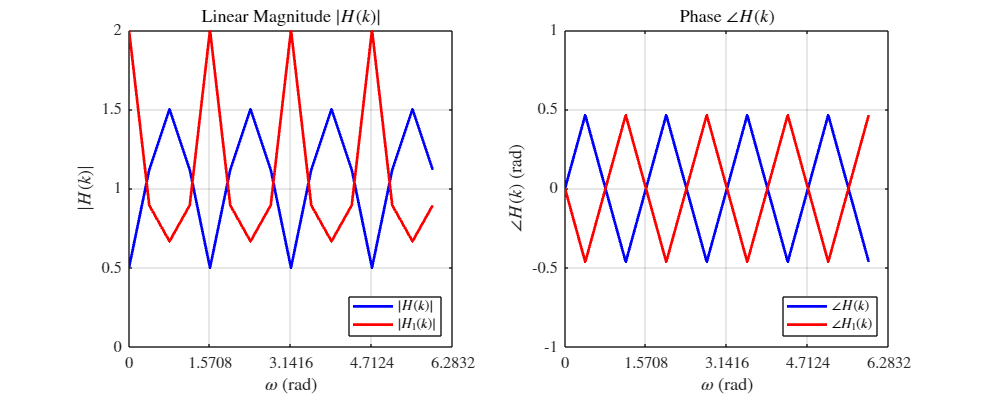

N = 16;

% Perform N-point FFT on h(n), then calculate linear magnitude and phase of H(k).
H = fft(h, N); % FFT.
H_magnitude = abs(H); % Linear magnitude.
H_phase = angle(H); % Phase plot

% Calculate H1(k) by inversing eaching of H(k), then calculate linear magnitude and phase of H1(k).
H1 = 1./H;
H1_magnitude = abs(H1); % Linear magnitude.
H1_phase = angle(H1); % Phase.

% Define the frequency vector.
Frequency = (0:1:N-1)'*(2*pi)/N;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H_magnitude, 'b', 'LineWidth', 2);
plot(Frequency, H1_magnitude, 'r', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H(k)|$');
legend('$|H(k)|$', '$|H_{1}(k)|$', 'Location', 'Southeast')
title('Linear Magnitude $|H(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H_phase, 'b', 'LineWidth', 2);
plot(Frequency, H1_phase, 'r', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H(k)$ (rad)');
legend('$\angle H(k)$', '$\angle H_{1}(k)$', 'Location', 'Southeast');
title('Phase $\angle H(k)$');

Figure B1. Linear magnitude and phase of *H*(*k*) and *H*1(*k*).

2. Obtain *h*1(*n*) and plot *h*1(*n*) and the zero locations of *H*1(*z*).

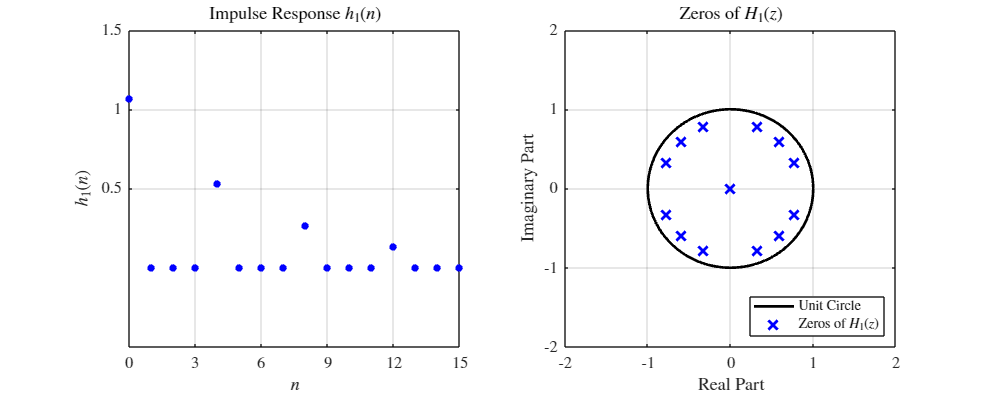

% Perform IFFT to calculate h1(n).
h1 = ifft(H1, N);

% Calculate roots of the polynomial.
H1_zeros = roots(h1);

figure('Position',[0 0 1000 400]);

% Plot the impulse response h1(n).
subplot(1,2,1);
hold on;
scatter(0:1:N-1, h1, 30, 'o', 'b', 'filled');
grid on;
box on;
xlim([0 15]);
xticks(0:3:15);
ylim([-0.5 1.5]);
yticks(0.5:0.5:1.5);
xlabel('$n$');
ylabel('$h_{1}(n)$');
title('Impulse Response $h_{1}(n)$');

% Plot the zero locations of H1(z).
subplot(1,2,2);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the zero locations.
plot(real(H1_zeros), imag(H1_zeros), 'x', 'Color', 'b', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H_{1}(z)$');
legend('Unit Circle', 'Zeros of $H_{1}(z)$', 'Location', 'southeast');

Figure B2.  Impulse response function *h*1(*n*) and zero locations of *H*1(*z*).

3. Augment *h*1(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*1(*k*) vs. ω.

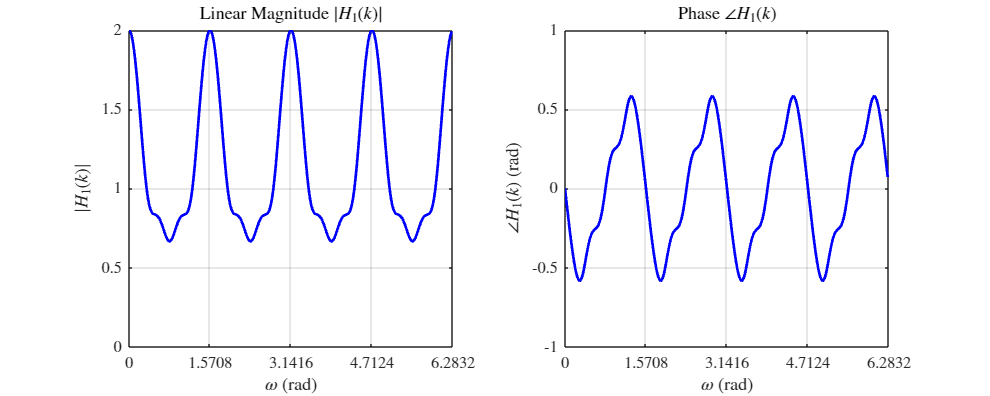

% Zero-pad h1(n) with zeros out to NFFT=256.
NFFT = 256;
h1_NFFT = padarray(h1, NFFT-size(h1,1), 'post'); 

% Perform FFT on the padded h1(n), then calculate linear magnitude and phase.
H1_NFFT = fft(h1_NFFT); % FFT.
H1_NFFT_magnitude = abs(H1_NFFT); % Linear magnitude.
H1_NFFT_phase = angle(H1_NFFT); % Phase.

% Define the frequency vector.
Frequency = (0:1:NFFT-1)'*(2*pi)/NFFT;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H1_NFFT_magnitude, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H_{1}(k)|$');
title('Linear Magnitude $|H_{1}(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H1_NFFT_phase, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H_{1}(k)$ (rad)');
title('Phase $\angle H_{1}(k)$');

Figure B3. Linear magnitude and phase of *H*1(*k*).

4. Obtain the linear convolution *h*2(n) = *h*(*n*) * *h*1(*n*) via FFT (2*N* = 32 point result).

% Perform 2N-point FFT on h(n) and h1(n).
H_2N = fft(h, 2*N);
H1_2N = fft(h1, 2*N);

% Calculate H2(k) by multiplication in frequency domain.
H2_2N = H_2N .* H1_2N;

% Perform IFFT to obtain h2(n).
h2_2N = ifft(H2_2N);

5. Plot *h*2(*n*) and zero locations of *H*2(*z*). Note: Trailing zeros in the 2*N*-point result for *h*2(*n*) should be truncated prior to determining zero locations for *H*2(*z*).

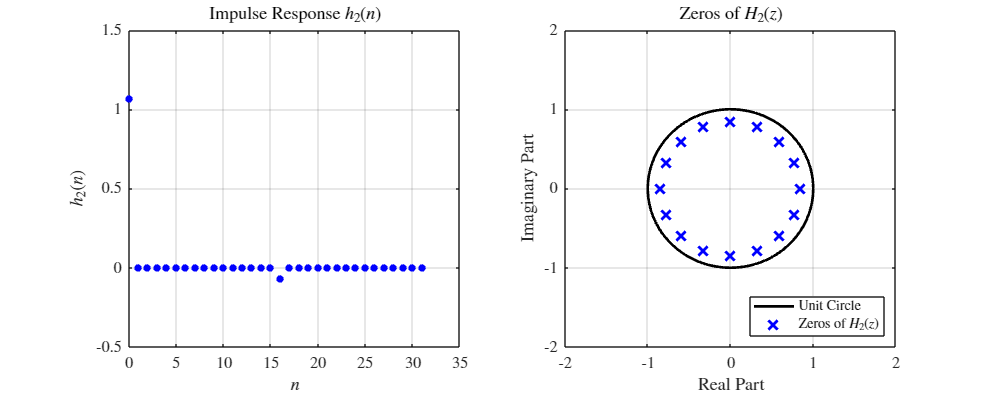

% Find the index for the last non-zero value in h2(n).
LastNonzeroIndex = find(abs(h2_2N) > 1e-6, 1, 'last');

% Calculate roots of the polynomial.
H2_2N_zeros = roots(h2_2N(1:LastNonzeroIndex));

figure('Position',[0 0 1000 400]);

% Plot the impulse response h2(n).
subplot(1,2,1);
hold on;
scatter(0:1:2*N-1, h2_2N, 30, 'o', 'b', 'filled');
grid on;
box on;
xlim([0 35]);
xticks(0:5:35);
ylim([-0.5 1.5]);
yticks(-0.5:0.5:1.5);
xlabel('$n$');
ylabel('$h_{2}(n)$');
title('Impulse Response $h_{2}(n)$');

% Plot the zero locations of H2(z).
subplot(1,2,2);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the zero locations.
plot(real(H2_2N_zeros), imag(H2_2N_zeros), 'x', 'Color', 'b', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H_{2}(z)$');
legend('Unit Circle', 'Zeros of $H_{2}(z)$', 'Location', 'southeast');

Figure B4.  Impulse response function *h*2(*n*) and zero locations of *H*2(*z*).

6. Augment *h*2(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*2(*k*) vs. ω.

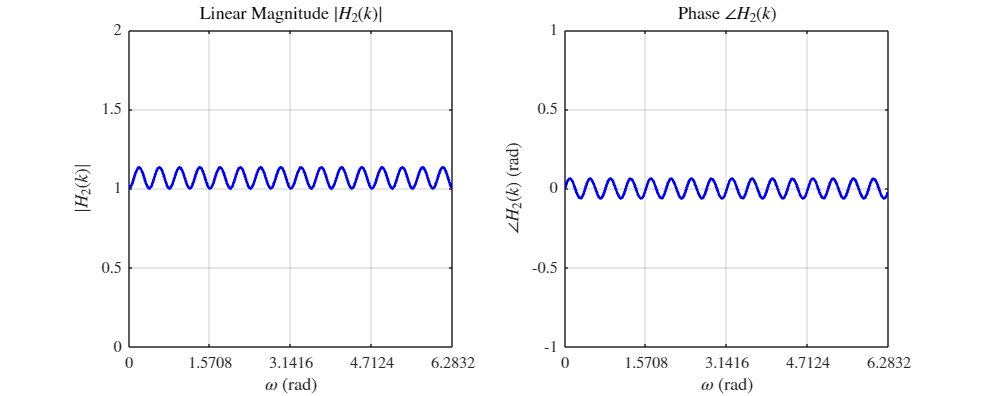

% Zero-pad h2(n) with zeros out to NFFT=256.
NFFT = 256;
h2_NFFT = padarray(h2_2N, NFFT-size(h2_2N,1), 'post'); 

% Perform FFT on the padded h2(n), then calculate linear magnitude and phase.
H2_NFFT = fft(h2_NFFT); % FFT.
H2_NFFT_magnitude = abs(H2_NFFT); % Linear magnitude.
H2_NFFT_phase = angle(H2_NFFT); % Phase.

% Define the frequency vector.
Frequency = (0:1:NFFT-1)'*(2*pi)/NFFT;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H2_NFFT_magnitude, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H_{2}(k)|$');
title('Linear Magnitude $|H_{2}(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H2_NFFT_phase, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H_{2}(k)$ (rad)');
title('Phase $\angle H_{2}(k)$');

Figure B5. Linear magnitude and phase of *H*2(*k*).

#### C. Let *N* = 64: Repeat 1-6 in Part B.

1. Obtain the *N*-point DFT *H*(*k*) of *h*(*n*) and the *N*-point DFT *H*1(*k*) of *h*1(*n*), where $H_1 \left(k\right)=\frac{1}{H\left(k\right)}$ samples the Fourier transform of the true inverse system $H_1 \left(z\right)=\frac{1}{H\left(z\right)}$. Plot linear magnitude and phase of *H*(k) and *H*1(*k*) vs *ω*.

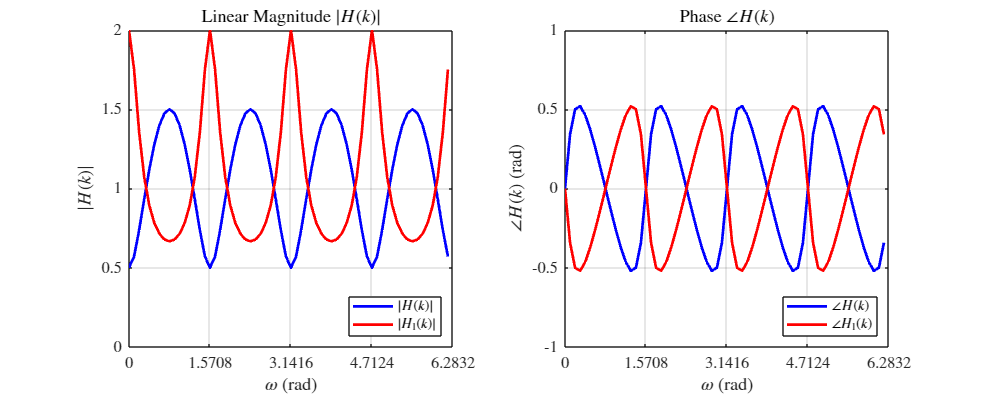

N = 64;

% Perform N-point FFT on h(n), then calculate linear magnitude and phase of H(k).
H = fft(h, N); % FFT.
H_magnitude = abs(H); % Linear magnitude.
H_phase = angle(H); % Phase plot

% Calculate H1(k) by inversing eaching of H(k), then calculate linear magnitude and phase of H1(k).
H1 = 1./H;
H1_magnitude = abs(H1); % Linear magnitude.
H1_phase = angle(H1); % Phase.

% Define the frequency vector.
Frequency = (0:1:N-1)'*(2*pi)/N;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H_magnitude, 'b', 'LineWidth', 2);
plot(Frequency, H1_magnitude, 'r', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H(k)|$');
legend('$|H(k)|$', '$|H_{1}(k)|$', 'Location', 'Southeast')
title('Linear Magnitude $|H(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H_phase, 'b', 'LineWidth', 2);
plot(Frequency, H1_phase, 'r', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H(k)$ (rad)');
legend('$\angle H(k)$', '$\angle H_{1}(k)$', 'Location', 'Southeast');
title('Phase $\angle H(k)$');

Figure C1. Linear magnitude and phase of *H*(*k*) and *H*1(*k*).

2. Obtain *h*1(*n*) and plot *h*1(*n*) and the zero locations of *H*1(*z*).

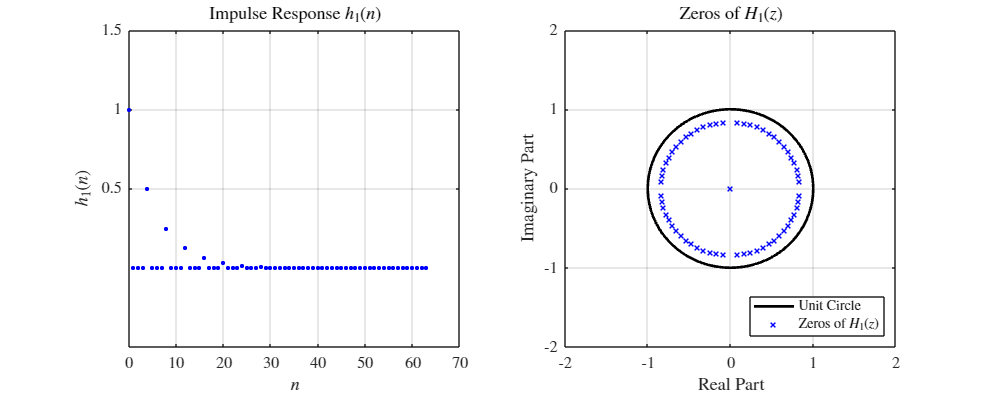

% Perform IFFT to calculate h1(n).
h1 = ifft(H1, N);

% Calculate roots of the polynomial.
H1_zeros = roots(h1);

figure('Position',[0 0 1000 400]);

% Plot the impulse response h1(n).
subplot(1,2,1);
hold on;
scatter(0:1:N-1, h1, 10, 'o', 'b', 'filled');
grid on;
box on;
xlim([0 70]);
xticks(0:10:70);
ylim([-0.5 1.5]);
yticks(0.5:0.5:1.5);
xlabel('$n$');
ylabel('$h_{1}(n)$');
title('Impulse Response $h_{1}(n)$');

% Plot the zero locations of H1(z).
subplot(1,2,2);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the zero locations.
plot(real(H1_zeros), imag(H1_zeros), 'x', 'Color', 'b', 'MarkerSize', 5, 'LineWidth', 1);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H_{1}(z)$');
legend('Unit Circle', 'Zeros of $H_{1}(z)$', 'Location', 'southeast');

Figure C2.  Impulse response function *h*1(*n*) and zero locations of *H*1(*z*).

3. Augment *h*1(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*1(*k*) vs. ω.

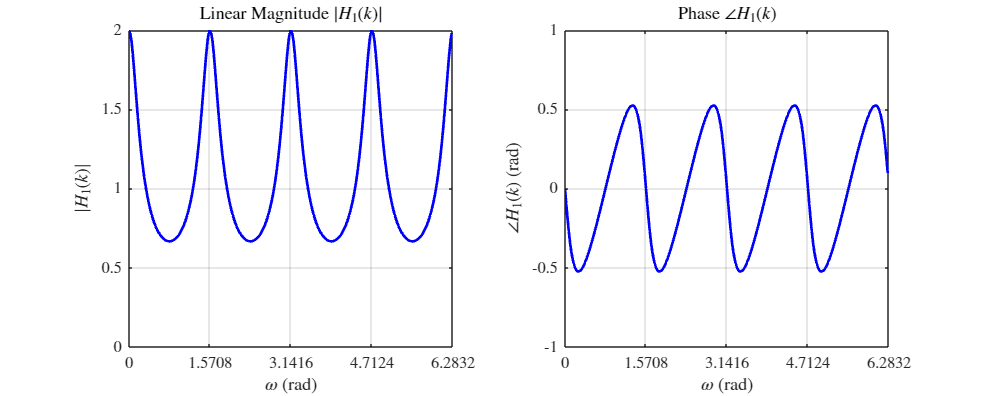

% Zero-pad h1(n) with zeros out to NFFT=256.
NFFT = 256;
h1_NFFT = padarray(h1, NFFT-size(h1,1), 'post'); 

% Perform FFT on the padded h1(n), then calculate linear magnitude and phase.
H1_NFFT = fft(h1_NFFT); % FFT.
H1_NFFT_magnitude = abs(H1_NFFT); % Linear magnitude.
H1_NFFT_phase = angle(H1_NFFT); % Phase.

% Define the frequency vector.
Frequency = (0:1:NFFT-1)'*(2*pi)/NFFT;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H1_NFFT_magnitude, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H_{1}(k)|$');
title('Linear Magnitude $|H_{1}(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H1_NFFT_phase, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H_{1}(k)$ (rad)');
title('Phase $\angle H_{1}(k)$');

Figure C3. Linear magnitude and phase of *H*1(*k*).

4. Obtain the linear convolution *h*2(n) = *h*(*n*) * *h*1(*n*) via FFT (2*N* = 32 point result).

% Perform 2N-point FFT on h(n) and h1(n).
H_2N = fft(h, 2*N);
H1_2N = fft(h1, 2*N);

% Calculate H2(k) by multiplication in frequency domain.
H2_2N = H_2N .* H1_2N;

% Perform IFFT to obtain h2(n).
h2_2N = ifft(H2_2N);

5. Plot *h*2(*n*) and zero locations of *H*2(*z*). Note: Trailing zeros in the 2*N*-point result for *h*2(*n*) should be truncated prior to determining zero locations for *H*2(*z*).

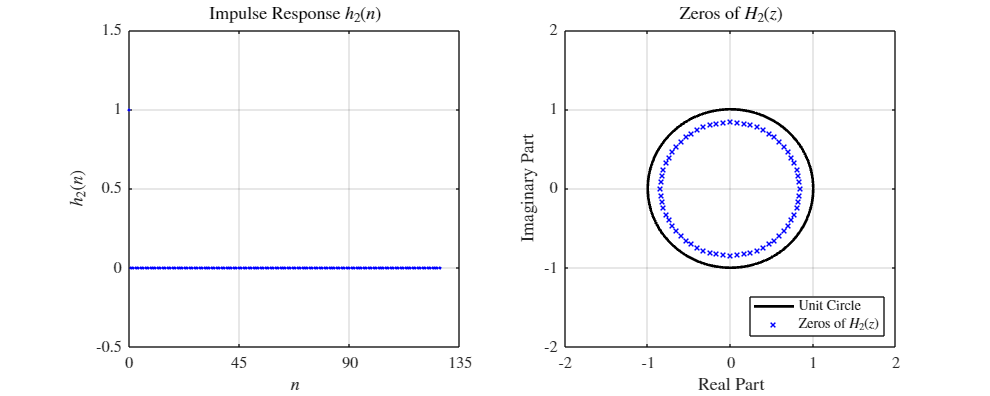

% Find the index for the last non-zero value in h2(n).
LastNonzeroIndex = find(abs(h2_2N) > 1e-6, 1, 'last');

% Calculate roots of the polynomial.
H2_2N_zeros = roots(h2_2N(1:LastNonzeroIndex));

figure('Position',[0 0 1000 400]);

% Plot the impulse response h2(n).
subplot(1,2,1);
hold on;
scatter(0:1:2*N-1, h2_2N, 5, 'o', 'b', 'filled');
grid on;
box on;
xlim([0 135]);
xticks(0:45:135);
ylim([-0.5 1.5]);
yticks(-0.5:0.5:1.5);
xlabel('$n$');
ylabel('$h_{2}(n)$');
title('Impulse Response $h_{2}(n)$');

% Plot the zero locations of H2(z).
subplot(1,2,2);
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 2);

% Plot the zero locations.
plot(real(H2_2N_zeros), imag(H2_2N_zeros), 'x', 'Color', 'b', 'MarkerSize', 5, 'LineWidth', 1);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H_{2}(z)$');
legend('Unit Circle', 'Zeros of $H_{2}(z)$', 'Location', 'southeast');

Figure C4.  Impulse response function *h*2(*n*) and zero locations of *H*2(*z*).

6. Augment *h*2(*n*) with zeros out to NFFT = 256, FFT, and plot linear magnitude and phase of *H*2(*k*) vs. ω.

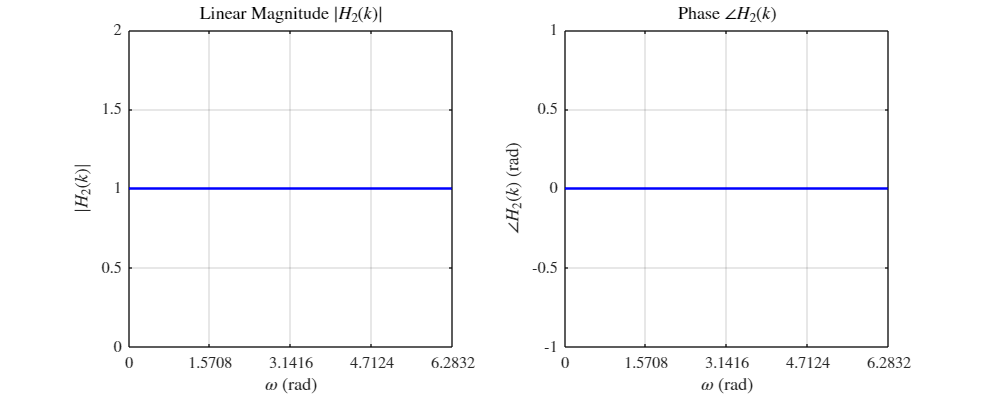

% Zero-pad h2(n) with zeros out to NFFT=256.
NFFT = 256;
h2_NFFT = padarray(h2_2N, NFFT-size(h2_2N,1), 'post'); 

% Perform FFT on the padded h2(n), then calculate linear magnitude and phase.
H2_NFFT = fft(h2_NFFT); % FFT.
H2_NFFT_magnitude = abs(H2_NFFT); % Linear magnitude.
H2_NFFT_phase = angle(H2_NFFT); % Phase.

% Define the frequency vector.
Frequency = (0:1:NFFT-1)'*(2*pi)/NFFT;

figure('Position',[0 0 1000 400]);

% Plot the linear magnitude.
subplot(1,2,1);
hold on;
plot(Frequency, H2_NFFT_magnitude, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([0 2]);
yticks(0:0.5:2);
xlabel('$\omega$ (rad)');
ylabel('$|H_{2}(k)|$');
title('Linear Magnitude $|H_{2}(k)|$');

% Plot the phase.
subplot(1,2,2);
hold on;
plot(Frequency, H2_NFFT_phase, 'b', 'LineWidth', 2);
grid on;
box on;
xlim([0 2*pi]);
xticks(0:0.5*pi:2*pi);
% xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'});
ylim([-1 1]);
yticks(-1:0.5:1);
xlabel('$\omega$ (rad)');
ylabel('$\angle H_{2}(k)$ (rad)');
title('Phase $\angle H_{2}(k)$');

Figure C5. Linear magnitude and phase of *H*2(*k*).